# MATLAB Getting Started

## 1 Übersicht

- Dies ist eine Live-Skript. Ein Live Skript ist eine Mischung aus formatiertem, erklärendem Text, Formeln und Bildern und MATLAB Code.

- Die Anteile MATLAB Code stehen in grau hinterlegen Bereichen.

3*3

ans = 9

- Wenn Sie oben im in der Toolbar den "Run".Knopf mit dem grünen Dreieck drücken, wird der Code ausgeführt und falls dabei ein Ergebnis entsteht, wird es unter dem Code angezeigt. Probieren Sie es aus!

- MATLAB ist eine Programmiersprache und das MATLAB Programm ist eine integrierte Entwicklungsumgebung (engl. integrated development environment, IDE).

- Da MATLAB eine interpretierte Sprache ist, kann jeder Ausdruck bzw. jede Anweisung direkt und einzeln in der sogenannten *Kommandozeile* ausgeführt werden (vgl. die folgenden Abbildung).

- Nach der Eingabe eines Ausdrucks oder einer Folge von Ausdrücken startet die Ausführung mit dem Drücken der Eingabetaste.

**Begleiten Sie die Code-Beispiele im Folgenden durch eigene Experimente in der Kommandozeile. Das selber ausprobieren festigt den gelernten Stoff!**

- Mehrere Ausdrücke können durch ein **Komma** oder ein **Semikolon** getrennt werden.

3*3, 4*4

ans = 9

ans = 16

        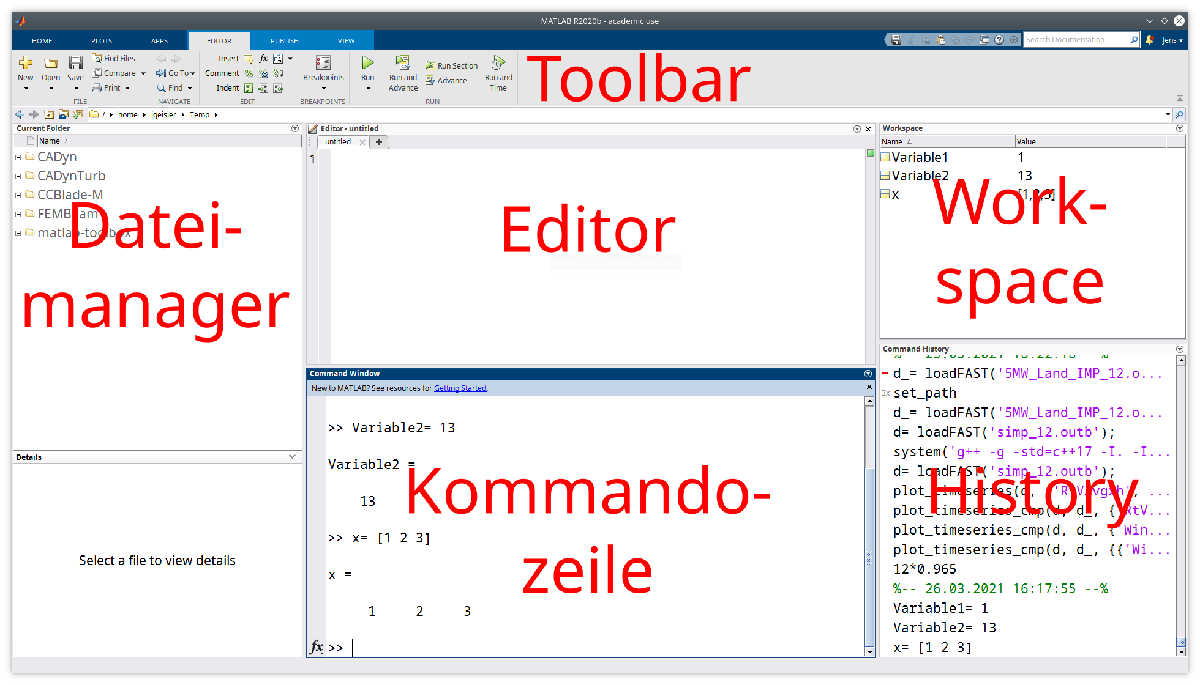

- Viele Ausdrücke erzeugen eine Ausgabe, die direkt nach der Ausführung in der Kommandozeile angezeigt wird. Diese Ausgabe kann durch ein **Semikolon** am Ende des Ausdrucks unterdrückt werden. Dies ist besonders bei Ausdrücken, die andernfalls eine sehr lange Ausgabe zur Folge hätten, sehr ratsam.

13

ans = 13

13;

- Mehrere Ausdrücke können mit dem *Editor* in eine Datei, ein sogenanntes Skript, geschrieben werden. Ein Skript kann als ganzes aufgerufen bzw. ausgeführt werden, indem im *Toolbar* der dreieckige grüne „Run“-Knopf gedrückt wird, oder der Name des Skripts ohne den Anhang „.m“ in der Kommandozeile aufgerufen wird.

- In Skripten können auch mit Schleifen und bedingten Anweisungen ganze Programme geschreiben werden. Dazu später mehr.

- Skripte können nur ausgeführt werden, wenn sie im Suchpfad zu finden sind, oder im aktuellen Verzeichnis stehen. Das aktuelle Verzeichnis ist das, dessen Inhalt im *Dateimanager* angezeigt wird.

- Alle Ausdrücke in einem Skript sollten mit einem Semikolon enden.

- **Leerzeichen** in Ausdrücken haben keine Bedeutung (außer einer optischen Formatierung zur Verbesserung der Lesbarkeit) und werden ignoriert.

- Alles hinter einem Prozentzeichen ist eine Kommentar.

13 % Kommentar

ans = 13

- Alle Variablen, die an der Kommandozeile oder in Skripten zugewiesen werden, werden im *Workspace* gespeichert. Ein Doppelklick auf eine Variable im Workspace öffnet eine Ansicht, in der der Inhalt der Variablen genauer untersucht werden kann. Diese Ansicht Teilt sich den gleichen Bildschirmbereich mit dem Editor. Über diesem Bereich befinden sich Reiter, mit denen Sie zwischen dem Editor und der Variablenansicht hin und her wechseln können.

x= 13; % x ist eine Variabel, die nach dem Ausführen im Workspace zu finden ist

- Alle Befehle, die Sie in der Kommandozeile eingeben, werden in der History gespeichert. Wenn die History bei Ihnen nicht wie im oben gezeigten Bild angezeigt wird, können Sie sie wie folgt aktivieren: im Toolbar unter dem Reiter „HOME“, im Bereich „ENVIRONMENT“ muss unter „Layout/Command History“ „docked“ angehakt werden.

- In der Kommandozeile können Sie die Eingabe auf zwei Arten beschleunigen:

- Wenn Sie einen Befehl ausführen möchten, der schon in der History steht, können Sie die ersten Buchstaben des Befehls eingeben und dann mit der Pfeil-Hoch-Taste nacheinander alle Befehle aus der History hervorholen, die mit diesen Buchstaben beginnen. Wenn Sie die Pfeil-Hoch-Taste bei leerer Kommandozeile drücken, erscheinen einfach alle Befehle aus der History nacheinander. Sobald sie einmal in diesem Modus sind, können Sie natürlich auch die Pfeil-Runter-Taste zum zurückgehen verwenden.

- Mit der Tabulatortaste können Sie MATLAB bekannte Befehle und Variablen nach der Eingabe der ersten paar Buchstaben automatisch vervollständigen (auto complete). Dies geht auch mehrfach in einer Zeile, wenn Sie z.B. nacheinander die Argumente in einem Funktionsaufruf festlegen.

- Mit der „Esc“ Taste können Sie die Kommandozeile leeren.

## 2 Zahlen

- Das Komma ist ein MATLAB immer ein Punkt!

1.1

ans = 1.1000

- Komplexe Zahlen werden als Summe aus dem reelen und dem imaginären Anteil eingegeben. Der imaginäre Anteil wird mit einem „`i`“ gekennzeichnet.

13-5i

ans = 13.0000 - 5.0000i

- Sehr große und sehr kleine Zahlen können in der Exponenzielschreibweise eingegeben werden:

1.2e3

ans = 1200

1.2e-3

ans = 0.0012

- Eine besondere Zahl ist Unendlich:

inf

ans = Inf

-1/0

ans = -Inf

- Eine weiter besondere Zahl ist die „Not-a-Number“ (`Nan`):

nan

ans = NaN

0/0

ans = NaN

- Weitere spezielle Zahlen, mit einem eigenen Namen sind `pi` und eps. `eps` ist die Differenz zwischen 1 und der nächst größeren darstellbaren Zahl.

pi

ans = 3.1416

eps

ans = 2.2204e-16

- MATLAB kann auch andere Zahlentypen verarbeiten, aber ohne weitere Angaben,  ist in MATLAB alles eine[Gleitkommazahl](https://de.wikipedia.org/wiki/Gleitkommazahl) mit doppelter Genauigkeit (`double`).

## 3 Einfache Rechenoperationen

### 3.1 Algebra und Funktionen

- In MATLAB stehen die Operatoren "`+`", "`-`", "`*`", "`/`" und die Klammern mit den gewohnten Funktionen zur Verfügung. Das "Hütchen!-Zeichen "`^`" ist der Operator für das Exponenzieren.

(x+1)/2

ans = 7

2^-0.5

ans = 0.7071

- Weiterhin stehen die üblichen mathematischen Funktionen zur Verfügung

- `exp, log, log10, ln`

- `sqrt`

- `mod, rem`

- `cos, sin, tan, acos, asin, atan, sinh, cosh, tanh`

- `abs, sign`

- `imag, real, conj, angle`

- `round, floor, ceil`

exp(1i*pi)

ans = -1.0000 + 0.0000i

real(exp(1i*pi))

ans = -1

mod(floor(3.7), 2)

ans = 1

- Weitere Informationen erhalten Sie mit der HIlfe-Funktion

help sign

 sign   Signum function.
    For each element of X, sign(X) returns 1 if the element
    is greater than zero, 0 if it equals zero and -1 if it is
    less than zero.  For the nonzero elements of complex X,
    sign(X) = X ./ ABS(X).
 
    See also abs.

    Documentation for sign



- **Nutzen Sie die Hilfe-Funktion ausgiebig! Lesen mehr als nur den Teil, der sie aktuell interessiert! Seien Sie neugierig auf das "See also" am Ende eines jeden Hilfetexts!**

- Die Hilfe wird Ihr größter Lehrmeister sein.

- Hübscher formatierten Hilfetext erhalten Sie, indem Sie auf den "Documentation for"-Link am Ende des Hilfetexts klicken, oder indem Sie oben rechts im MATLAB Fenster auf das Fragezeichen klicken und dort nach den gewünschten Inhalten suchen.

### 3.2 Relationsoperatoren

- Wenn Sie die Relationsoperatoren "`==`", "`~=`" (ist nicht), "`>`", "`<`", "`>=`", "`<=`" auf Zahlen anwenden, ist das Ergebnis ein boolscher Wert bzw. ein logical:

1~=1

ans = logical
   0


- Logicals können Sie mit den logischen Operatoren "`&`" (UND), "`|`" (senkrechter Strich, in Windows mit AltGr+Taste neben linkem Shift, ODER), "`~`" (NICHT), `xor(a, b)` verknüpfen:

0==0 & ~(1==0)

ans = logical
   1


## 4 Variablen und Datentypen

### **4.1 Allgemein**

- Variablennamen müssen mit einem Buchstaben beginnen, und können Buchstaben, Zahlen und Unterstrichen enthalten. Groß- und Kleinbuchstaben machen einen Unterschied.

- MATLAB ist eine Objekt-Orintierte Programmiersprache, sodass Variablen prinzipiell beliebig komplexte Objekte enthalten können.

- Standardmäßig wird Variablen jedoch eine Matrix aus (komplexen) Fließkommazahlen zugewiesen. Alles in MATLAB ist eine Matrix, selbst skalare Werte.

- Die Zuweisung wird mit dem Gleichheitszeichen vorgenommen, z.B.:

x= 1

x = 1

- Variablen können mit `clear` wieder aus dem Workspace gelöscht werden.

- Der gesamte Workspace kann mit `clear all` gelöscht werden.

- Der Inhalt des Workspace kann mit `who` angezeigt werden.

y= 2;
z= 3;
who


Your variables are:

ans  x    y    z    



clear x
who


Your variables are:

ans  y    z    



clear all
who

### **4.2 Vektoren und Matrizen**

- Bei der Eingabe werden Vektoren durch eckige Klammern dargestellt:

x= [1, 3, 5 6]

x =      1     3     5     6


- In Zeilenvektoren können dei Elemente mit Kommat und/oder Leerzeichen getrennt werden. Mehrere Zeilen, bzw. die Elemente in einem Spaltenvektor werden mit einem Semikolon getrennt:

x= [1; 3; 5; 6]

x =      1
     3
     5
     6


y= [1 2; 3 4]

y =      1     2
     3     4


- Der **Hochkomma** "`'`" Operator (Shift+#) transponiert eine Matrix:

[1 2 3]

ans =      1     2     3


[1 2 3]'

ans =      1
     2
     3


- Mit `zeros` lassen sich Matrizen mit Nullen erzeugen, mit `ones` Matrizen, die mit Einsen gefüllt sind und damit .

zeros(1, 3)

ans =      0     0     0


13*ones(1, 4)

ans =     13    13    13    13


- Eine Einheitsmatrix kann mit dem `eye` Befehl erzeugt werden:

eye(3)

ans =      1     0     0
     0     1     0
     0     0     1


- Eine besondere Methode, Vektoren zu erzeugen, ist der Doppelpunktoperator:

x= 2:5

x =      2     3     4     5


y= -3:0.25:1

y =    -3.0000   -2.7500   -2.5000   -2.2500   -2.0000   -1.7500   -1.5000   -1.2500   -1.0000   -0.7500   -0.5000   -0.2500         0    0.2500    0.5000    0.7500    1.0000


- Eine weitere Methode ist die `linspace`-Funktion. Finden Sie heraus, welche Bedeutung die drei Argumente haben!

x= linspace (1, 2.33, 7)

x =     1.0000    1.2217    1.4433    1.6650    1.8867    2.1083    2.3300


- In Rechenoperationen lassen sich immer skalare Werte und Vektoren/Matrizen miteineander kombinieren. Die skalaren Operationen werden dann auf alle Werte des Vektors / der Matrix angewendet. Das nennt sich "scalar expansion".

x= 2 * rand(1, 12) - 1;   % 12 Zufallszahlen von -1 bis +1

- Operationen in denen beider Operanden eine Matrix sind, sind als Matrixoperation definiert. Sie funktionieren nur, wenn die Dimensionen stimmen. Probieren Sie die nicht erlaubten Operationen an der Kommandozeile aus!

% [1 2 3] * [1 2 3] % das geht nicht
% [1 2 3] + [1 2] % das geht nicht

- ... und die Reihenfolge ist bei Matrixmultiplikationen auch entscheident.

[1 2 3]' * [1 2 3]

ans =      1     2     3
     2     4     6
     3     6     9


[1 2 3] * [1 2 3]'

ans = 14

- Elementweise Operationen werden mit einem **Punkt** vor dem Operator gekennzeichnet. Auch für sie gilt natürlich, dass die Dimensionen der Operanden zueinander passen müssen.

[1 2 3].*[1 2 3]

ans =      1     4     9


[1 2 3].^2

ans =      1     4     9


- Das normale Geteiltzeichen entspricht einer Rechtsmultiplikation mit der Inversen:

eye(2)/magic(2)

ans =    -0.2000    0.3000
    0.4000   -0.1000


magic(2)^-1

ans =    -0.2000    0.3000
    0.4000   -0.1000


inv(magic(2))

ans =    -0.2000    0.3000
    0.4000   -0.1000


- Eine Linksmultiplikation mit der Inversen kann mit dem **Rückwärtsschrägstrich** durchgeführt werden:

magic(3)\magic(3)

ans =     1.0000   -0.0000         0
         0    1.0000         0
         0    0.0000    1.0000


- Einzelne Elemente einer Matrix werden mit **runden Klammern** indiziert. Vektoren haben einen Index, Matrizen zwei. Bei Matrizen wird erst die Zeile und dann die Spalte indiziert.

- **Das erste Element hat den Index 1, nicht wie  in C oder Java die 0!**

x= 1;
x(1)

ans = 1

x

x = 1

x= magic(2);
x(1, 2)

ans = 3

- Auch Matrizen lassen sich mit einem Index indizieren. Dann werden die Elemente erst in den Spalten von oben nach unten und dann Spaltenweise von links nach rechts nummeriert.

x(3)

ans = 3

- Auch leere Matrizen sind zulässig.

x= [];

- Matrizenelemente können auch zugewiesen werden.

x(1)= 3;

- Wenn in eine Element zugewiesen wird, das noch nicht existiert, wird zunächst die Dimension angepasst und alle neuen Elemente werden mit Nullen gefüllt:

x(3)= 1

x =      3     0     1


- In MATLAB sind theoretisch mit unendlich vielen Dimensionen möglich.

x(1, 1, 3)= 1

x = x(:,:,1) =

     3     0     1


x(:,:,2) =

     0     0     0


x(:,:,3) =

     1     0     0


- Es können auch mehrere Elemente auf einmal indiziert werden. Dazu gibt es zwei Möglichkeiten:

- Der Index ist eine Vektor aus ganzen Zahlen.

- Der Index ist ein `logical` Vektor, dessen Dimension zur Anzahl der Spalten/Zeilen passt. Mit dieser Methode werden alle Ellemente indiziert, deren entsprechender Wert in den dem Vektor `1` bzw. `true` ist.

- Dieser Vektoren können natürlich auch in einer Variablen stehen!

t= 0:0.1:1;
t(1:3)

ans =          0    0.1000    0.2000


index_zahl= [1 3 4 7];
t(index_zahl)

ans =          0    0.2000    0.3000    0.6000


index_bool= t<0.5

index_bool = 1×11 logical array
   1   1   1   1   1   0   0   0   0   0   0


t(index_bool)

ans =          0    0.1000    0.2000    0.3000    0.4000



x= magic(5);
x(2, 1:3)

ans =     23     5     7


- Eine besondere Methode ist die Indizierung aller Werte in einer Zeile bzw. Spalte mit dem **Doppelpunktoperator**:

x(2, :)

ans =     23     5     7    14    16


- Weiterhin kann mit dem speziellen Schlüsselwort `end` das letzte Element der jeweiligen Dimension indiziert werden.

- Mit `end` kann auch gerechnet werden und **Doppelpunktoperator **zur Erzeugung von Bereichen kombinieren:

x(end-3, 3:end)

ans =      7    14    16


### 4.3 Zeichenketten

- Ein spezieller Datentyp in MATLAB sind Zeichen. Sie werden in einfachen **Hochkommata** (gleicehs Zeichen wie die Transposition) gesetzt.

- Mehrere Zeichen lassen sich ach direkt zusammen in einen Vektor schreiben.

- Zeichenvektoren haben alle Eigenschaften, wie normale Vektoren.

s= '123abc'

s = '123abc'

s(2)

ans = '2'

s(3)= '4'

s = '124abc'

- Mit Zeichenvektoren kann sogar gerechnet werden.

s+1

ans =     50    51    53    98    99   100


char(s+1)

ans = '235bcd'

- ... und sie können zusammengefügt werden.


s1= [s ' und noch ein bisschen mehr!']

s1 = '124abc und noch ein bisschen mehr!'

- Relativ neu in MATLAB sind sogenannte `strings`.

- Sie werden in **doppelte Anführungszeichen** gesetzt und ähneln mehr den Strings, die aus Java bekannt sind.

S= "Ein String"

S = "Ein String"

- Strings müssen mit join oder dem **Pluszeichen** zusammengefügt werden, ansonsten entstehen Vektoren mit mehreren Strings!

join([S, "wird länger"])

ans = "Ein String wird länger"

S+"wird länger"

ans = "Ein Stringwird länger"

[S "und noch einer"]

ans = 1×2 string array
    "Ein String"    "und noch einer"


### 4.4 Strukturen

- In MATLAB können adhoc Strukturdatentypen erstellt werden, ohne dass Sie vorher definiert werden müssen.

- Die Datenelemente einer Struktur (`struct`) heißen Felder.

- Felder werden mit dem Punktoperator adressiert.

- Wenn ein Feld bei der Zuweisung noch nicht existiert, wird es adhoc angelegt.

- Strukturen können auch Verschachtelt werden.

- Einzelne Felder können Daten unterschiedlichen Typs enthalten.

st= [] % diese Zuweisung ist nötig, um die Variable st zu löschen, falls sie schon existiert


st =

     []



st.a= 13

st = struct with fields:
    a: 13


st.b= magic(2)

st = struct with fields:
    a: 13
    b: [2×2 double]


st.c.a= 1e7

st = struct with fields:
    a: 13
    b: [2×2 double]
    c: [1×1 struct]


st.c.b= s

st = struct with fields:
    a: 13
    b: [2×2 double]
    c: [1×1 struct]


st_c= st.c

st_c = struct with fields:
    a: 10000000
    b: '124abc'


- Es sind auch Vektoren von Strukturen möglich.

- Alle Elemente eines Strukturvektors haben die gleichen Felder.

- Bei der Erweiterung eines Strukturvektors um eine Element werden alle Felder mit einer leeren Matrix vorbesetzt.

st(2).a= 14

st = 1×2 struct array with fields:
    a
    b
    c


st(2).d= pi

st = 1×2 struct array with fields:
    a
    b
    c
    d


- Wenn bei einem Strukturvektor ein Feld adressiert wird, wird eine sogenannte "comma separated list" zurückgegeben, mit der nicht direkt weiter gearbeitet werden kann.

- Eine "comma separated list" aus reinen Zahlen kann jedoch mit **eckigen Klammern** wieder zu einem Vektor zusammengefasst werden.

- Alle anderen Datentypen können mit geschweiften Klammern zu einem Cell-Array zusammen gefasst werden (siehe nächster Absachnitt).

st.a

ans = 13

ans = 14

[st.a]

ans =     13    14


st(1).e= 'test';
st(2).e= 'noch einer';
{st.e}

ans = 1×2 cell array
    {'test'}    {'noch einer'}


- Die Felder einer Struktur können an der Kommandozeile nach der Eingabe des Punkts mit der **Tabulatortaste** angezeigt bzw. automatisch vervollständigt werden.

- Ein paar wichtige Funktionen im Umgang mit Strukturen sind:

- `struct`

- `isstruct`

- `fieldnames`

- `isfield`

### 4.5 Cell-Arrays

- In normalen Matrizen kann jedes Element nur eine Zahl sein.

- In dem speziellen Datentyp `cell` kann jedes Element einen beliebigen, und von den anderen Elementen verschiedenen Datentypen haben.

- Elemente eines Cell-Arrays können natürlich auch wieder Cell-Arrays oder auch Strukturen sein.

- Cell-Arrays werden mit **geschweiften Klammern** erzeugt und indiziert.

c= {1 1:5 'bla'; [], st, S}

c = 2×3 cell array
    {[       1]}    {[1 2 3 4 5]}    {'bla'         }
    {0×0 double}    {1×2 struct }    {["Ein String"]}


c{1, 3}

ans = 'bla'

c{1, 4}= c

c = 2×4 cell array
    {[       1]}    {[1 2 3 4 5]}    {'bla'         }    {2×3 cell  }
    {0×0 double}    {1×2 struct }    {["Ein String"]}    {0×0 double}


- Die Unterelemente in einem Cell-Array können auch direkt weiter adressiert werden.

c{1,2}(2)

ans = 2

c{1,3}(1)

ans = 'b'

c{2,2}(1).a

ans = 13

- Bei Mehrfachindizierung mit **geschweiften Klammern** werden mehrer Ergebnisse zurückgegeben (Eine sogenannte "comma separated list"), mit denen nicht direkt weiter gearbeitet werden kann.

- Wwenn bei einer Mehrfachindizierung mit **runden Klammern** gearbeitet wird, entsteht wieder ein Cell-Array.

c(1, :)

ans = 1×4 cell array
    {[1]}    {[1 2 3 4 5]}    {'bla'}    {2×3 cell}


## 5 Weiterführende Literatur

Die folgenden beiden Links führen zu zwei Dokumenten, die weitere interessante Informationen zum Einstieg in MATLAB enthalten.

- [https://www.uni-muenster.de/AMM/num/Vorlesungen/MATLAB-Kurs_WS08/Script/matlab-einfuehrung.pdf](https://www.uni-muenster.de/AMM/num/Vorlesungen/MATLAB-Kurs_WS08/Script/matlab-einfuehrung.pdf)

- [http://staff.technikum-wien.at/~teschl/MatlabSkriptum.pdf](http://staff.technikum-wien.at/~teschl/MatlabSkriptum.pdf)